load Tests/Exp_MaxonMotors/simDoubleMotor
load Tests/Exp_MaxonMotors/expSetup

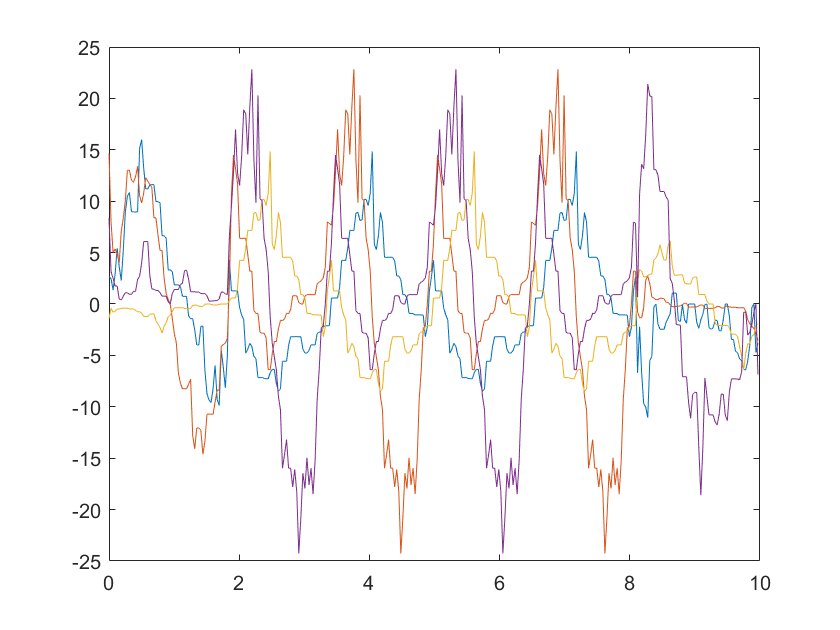

a = 1.6875e-4;
theta_f = 0;
theta_i = 0;
theta__dot_f = 0;
theta__dot_i = 0;
theta__ddot_i = 0;

theta = JointTrajFit(sm_t,a,t_f,theta_f,theta_i,theta__dot_f,theta__dot_i,theta__ddot_i);

plot(sm_t(1:end-1), convangvel(diff(sm_traj)/sm_t(2),'rad/s','rpm'))

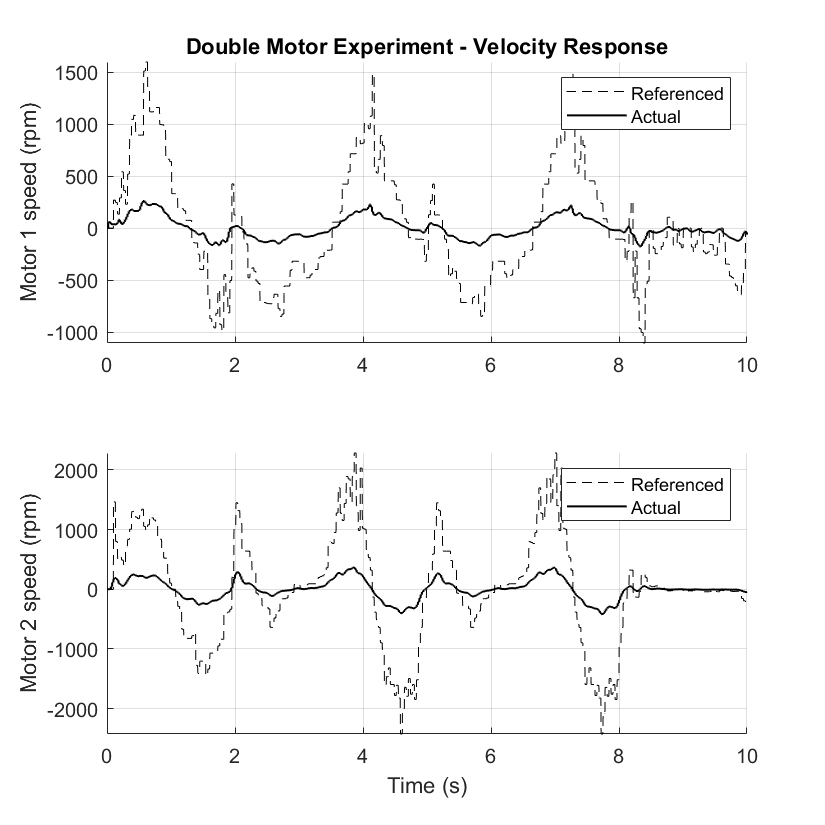

Motor1VelRef = simOut1.logsout{1}.Values.signal1;
Motor1VelAct = simOut1.logsout{1}.Values.Speed;
Motor2VelRef = simOut1.logsout{2}.Values.signal1;
Motor2VelAct = simOut1.logsout{2}.Values.Speed;

f = figure;
f.Position = [10 10 550 550];

subplot(2,1,1), hold on
plot(Motor1VelRef,'k--')
plot(Motor1VelAct,'k-','LineWidth',1)
title('Double Motor Experiment - Velocity Response')
legend('Referenced','Actual')
xlabel(''), ylabel('Motor 1 speed (rpm)')
grid on, axis tight, hold off

subplot(2,1,2), hold on
plot(Motor2VelRef,'k--')
plot(Motor2VelAct,'k-','LineWidth',1)
legend('Referenced','Actual')
xlabel('Time (s)'), ylabel('Motor 2 speed (rpm)')
grid on, axis tight, hold off

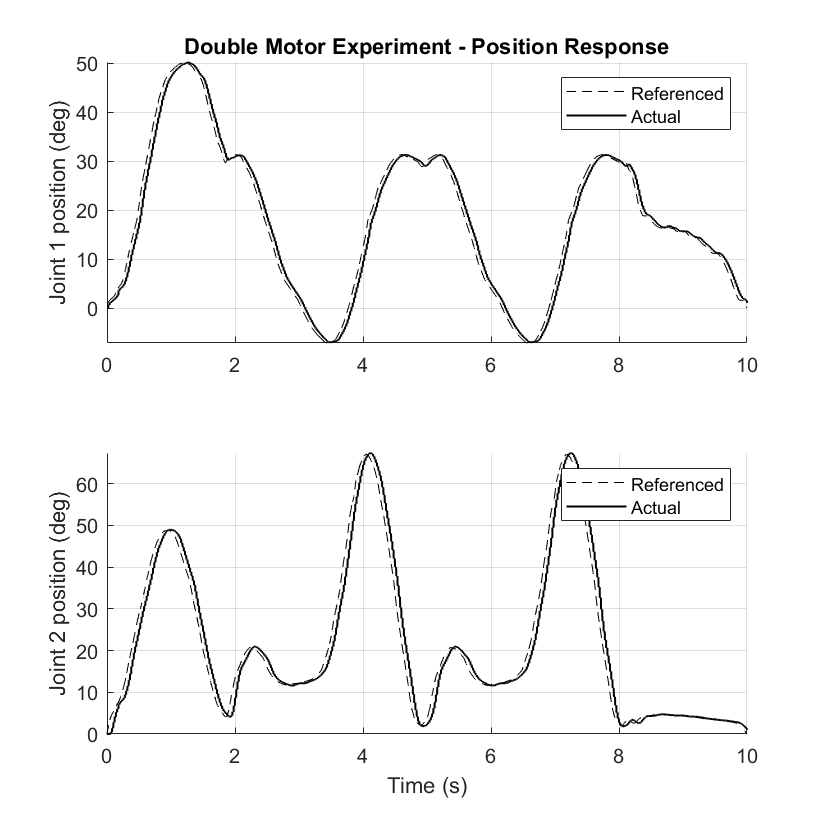

Motor1Pos = simOut1.logsout{5}.Values;
Motor2Pos = simOut1.logsout{6}.Values;
Motor1Cur = simOut1.logsout{3}.Values;
Motor2Cur = simOut1.logsout{4}.Values;

f = figure;
f.Position = [10 10 550 550];

subplot(2,1,1), hold on
p = plot(Motor1Pos,'Color','black');
p(1).LineStyle = '--';
p(2).LineWidth = 1;
title('Double Motor Experiment - Position Response')
legend('Referenced','Actual')
xlabel(''), ylabel('Joint 1 position (deg)')
grid on, axis tight, hold off

subplot(2,1,2), hold on
p = plot(Motor2Pos,'Color','black');
p(1).LineStyle = '--';
p(2).LineWidth = 1;
legend('Referenced','Actual')
xlabel('Time (s)'), ylabel('Joint 2 position (deg)')
grid on, axis tight, hold off

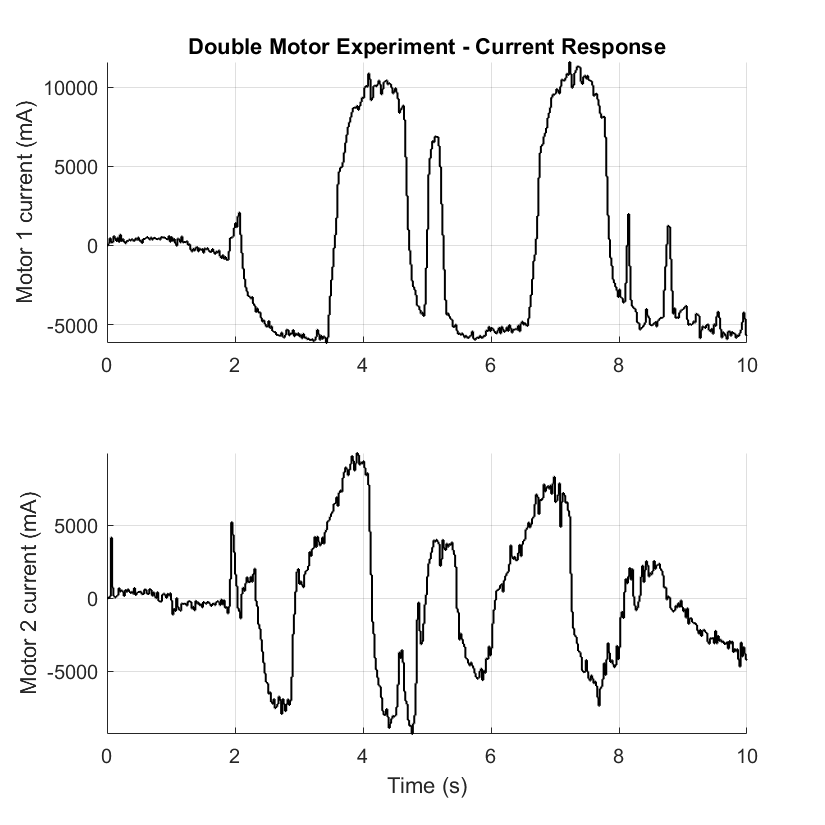

f = figure;
f.Position = [10 10 550 550];

subplot(2,1,1), hold on
plot(Motor1Cur,'k-','LineWidth',1);
title('Double Motor Experiment - Current Response')
xlabel(''), ylabel('Motor 1 current (mA)')
grid on, axis tight, hold off

subplot(2,1,2), hold on
plot(Motor2Cur,'k-','LineWidth',1);
xlabel('Time (s)'), ylabel('Motor 2 current (mA)')
grid on, axis tight, hold off

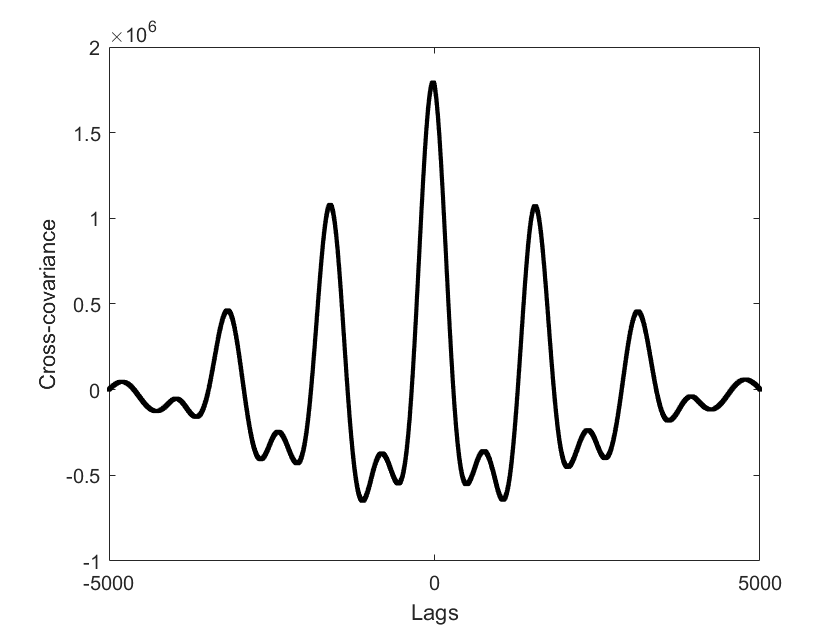


f = figure;
[cv, lags] = xcov(Motor2Pos.Data(:,1),Motor2Pos.Data(:,2));
plot(lags,cv,'k.')
xlabel('Lags'), ylabel('Cross-covariance')

corrcoef(Motor2Pos.Data(:,1),Motor2Pos.Data(:,2))

ans =     1.0000    0.9846
    0.9846    1.0000


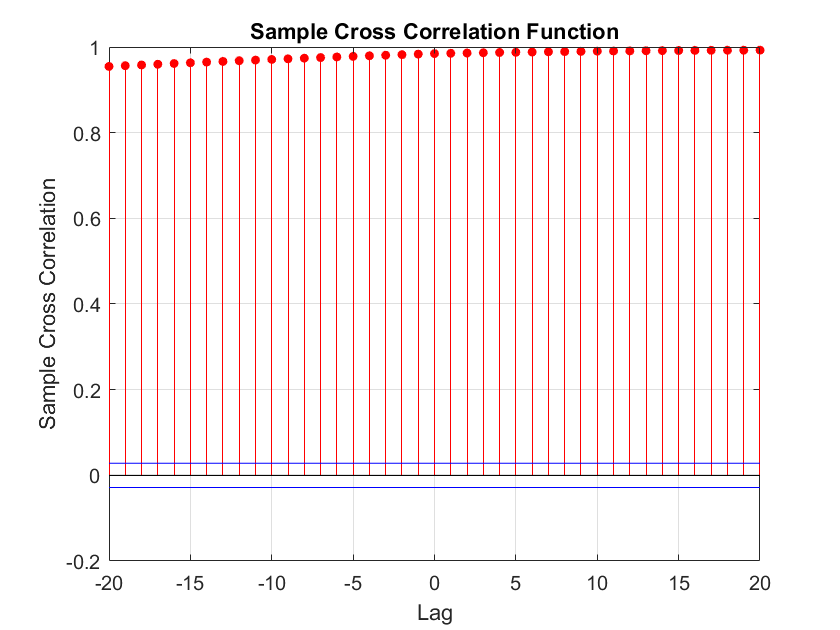

crosscorr(Motor2Pos.Data(:,1),Motor2Pos.Data(:,2))